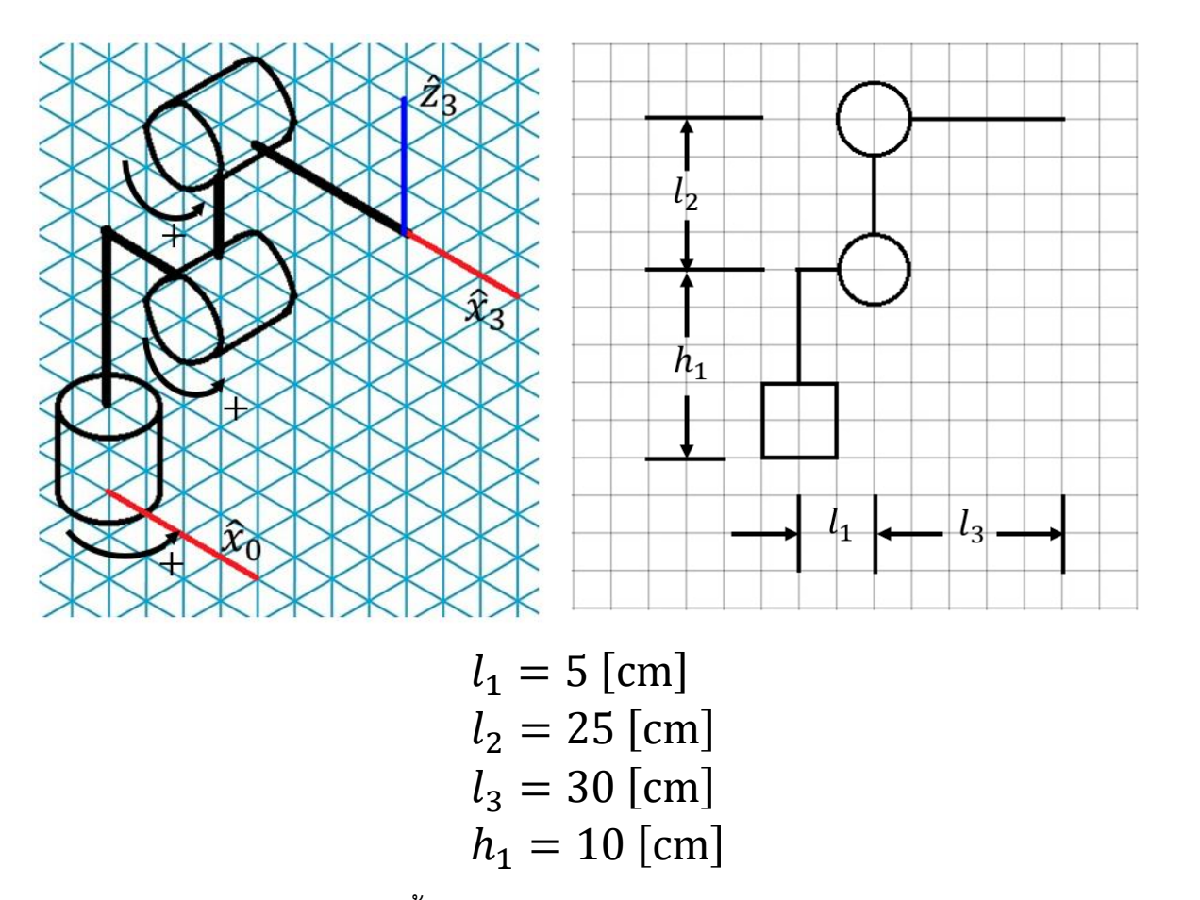                                                                                                                                                                                                                                

**input**

    .txt:    robot command = (2,n)

    .txt:    via_point_info = (3,m) // m = size of command via_points_task set in task space

**local variable**

    command = (1,n) L:0,J:1 

    via_point_task = (3,n) 

    via_point_joint_all = (3,n,4)

    via_point_joint = (3,n)

**step(function)**

readVariable => task2jointConversion =>  select optimal joint => gen C

**readVariable:** write .txt + return: via_point_task = (3,n), command = (1,n) L:0,J:1 

      Description: read variable

via_point_task_all ($\overrightarrow{\mathbf{P}}$)    : $\Re^{\mathrm{N}\times \mathrm{M}}$ which $\mathbf{N}$ is cartesian dimensions and $\mathbf{M}$ is number of via-point


$$\overrightarrow{\mathbf{P}} =\left\lbrack \begin{array}{cccc}
\overrightarrow{p_1 }  & \overrightarrow{p_2 }  & \overrightarrow{p_3 }  & \cdots 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccc}
p_{x_1 }  & p_{x_2 }  & p_{x_3 }  & \cdots \\
p_{y_1 }  & p_{y_2 }  & p_{y_3 }  & \cdots \\
p_{z_1 }  & p_{z_2 }  & p_{z_3 }  & \cdots 
\end{array}\right\rbrack$$


[command, via_point_task_all] = readVariable("robot_command_v0.txt", "via_points_info_v0.txt")

command =      1     1     1     0


via_point_task_all =     0.3500    0.5962    0.2621   -0.2621
         0         0         0         0
    0.3500    0.1434    0.5621    0.5621


**task2jointConversion:** return alert 0: cant access, 1: accessable; via_point_joint (3x4xn) D2: possible joint, D3: No. input via_point task

      Description: check possible access + convert task to joint

via_point_joint : $\Re^{\mathrm{K}\times \mathrm{M}\times \mathrm{S}}$ which $\mathbf{K}$ is number of joint, $\mathbf{M}$ is number of via-point and $\mathbf{S}$ is number of robot pose

[alert, via_point_joint] = task2jointConversion(via_point_task_all);
via_point_joint(:,:,1) = zeros(3,4);
via_point_joint

via_point_joint = via_point_joint(:,:,1) =

     0     0     0     0
     0     0     0     0
     0     0     0     0


via_point_joint(:,:,2) =

         0         0   99.0000   99.0000
   -1.5867   -1.3963   99.0000   99.0000
    1.7453    1.3963   99.0000   99.0000


via_point_joint(:,:,3) =

         0         0   99.0000   99.0000
   -0.8607         0   99.0000   99.0000
    2.3562    0.7854   99.0000   99.0000


via_point_joint(:,:,4) =

    3.1416    3.1416   99.0000   99.0000
   -0.8607         0   99.0000   99.0000
    2.3562    0.7854   99.0000   99.0000


**optimalPath: **return selected_via_point_joint (3xn)

selected_via_point_joint ($\overrightarrow{\mathbf{Q}}$)    : $\Re^{\mathrm{K}\times \mathrm{M}}$ which $\mathbf{K}$ is number of joint and $\mathrm{M}$ is number of via-point


$$\overrightarrow{\mathbf{Q}} =\left\lbrack \begin{array}{cccc}
\overrightarrow{q_1 }  & \overrightarrow{q_2 }  & \overrightarrow{q_3 }  & \cdots 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccc}
q_{1_1 }  & q_{1_2 }  & q_{1_3 }  & \cdots \\
q_{2_1 }  & q_{2_2 }  & q_{2_3 }  & \cdots \\
q_{3_1 }  & q_{3_2 }  & q_{3_3 }  & \cdots 
\end{array}\right\rbrack$$


[selected_via_point_joint, all_via_point_joint, cost] = optimalPath(via_point_joint, "shortest_path");

min_cost = 5.4978

min_idx = 5

selected_via_point_joint

selected_via_point_joint =          0         0         0    3.1416
         0   -1.3963   -0.8607   -0.8607
         0    1.3963    2.3562    2.3562


**coefficientGen: **return set of C, t_i, and tau

v_max = 1.75;
a_max = 0.5;
[C,t_i,T,alert_traj] = coefficientGen(selected_via_point_joint, v_max, a_max)

C = C(:,:,1) =

         0         0         0         0         0         0
         0         0         0   -0.2157    0.0806   -0.0080
         0         0         0    0.2157   -0.0806    0.0080


C(:,:,2) =

         0         0         0         0         0         0
   -1.3963         0         0    0.1451   -0.0654    0.0079
    1.3963         0         0    0.2601   -0.1172    0.0141


C(:,:,3) =

         0         0         0    0.1438   -0.0358    0.0024
   -0.8607         0         0         0         0         0
    2.3562         0         0         0         0         0


t_i =          0    4.0153    7.3446


T = 13.3676

alert_traj = 0

sampling = 1e-2; t = (0:sampling:T); %linspace(0,T,100+1);
p1 = [];
v1 = [];
a1 = [];

for i = 1:numel(t)
    k = discretize(t(i),[t_i T]);
   [p_j,v_j,a_j] = polyTrajEval(t(i),C(:,:,k),t_i(k));

    p1 = [p1 p_j];
    v1 = [v1 v_j];
    a1 = [a1 a_j];

end

[R,P,R_e,p_e] = forwardKine(p1);

p2 = p_e

p2 =     0.3500    0.3500    0.3500    0.3500    0.3500    0.3500    0.3500    0.3500    0.3500    0.3500    0.3501    0.3501    0.3501    0.3501    0.3501    0.3502    0.3502    0.3502    0.3503    0.3503    0.3504    0.3505    0.3505    0.3506    0.3507    0.3508    0.3509    0.3510    0.3511    0.3512    0.3513    0.3514    0.3516    0.3517    0.3519    0.3520    0.3522    0.3524    0.3526    0.3528    0.3530    0.3532    0.3534    0.3536    0.3539    0.3541    0.3544    0.3547    0.3549    0.3552
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    

v2 = [zeros(3,1) diff(p2')']

v2 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    

a2 = [zeros(3,1) diff(v2')']

a2 = 	1.0e+-4 *

         0    0.0005    0.0032    0.0064    0.0095    0.0126    0.0156    0.0185    0.0215    0.0244    0.0272    0.0300    0.0327    0.0354    0.0381    0.0407    0.0432    0.0457    0.0482    0.0506    0.0530    0.0554    0.0576    0.0599    0.0621    0.0643    0.0664    0.0685    0.0705    0.0725    0.0745    0.0764    0.0782    0.0801    0.0819    0.0836    0.0853    0.0870    0.0886    0.0902    0.0918    0.0933    0.0947    0.0962    0.0976    0.0989    0.1002    0.1015    0.1027    0.1039
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0  

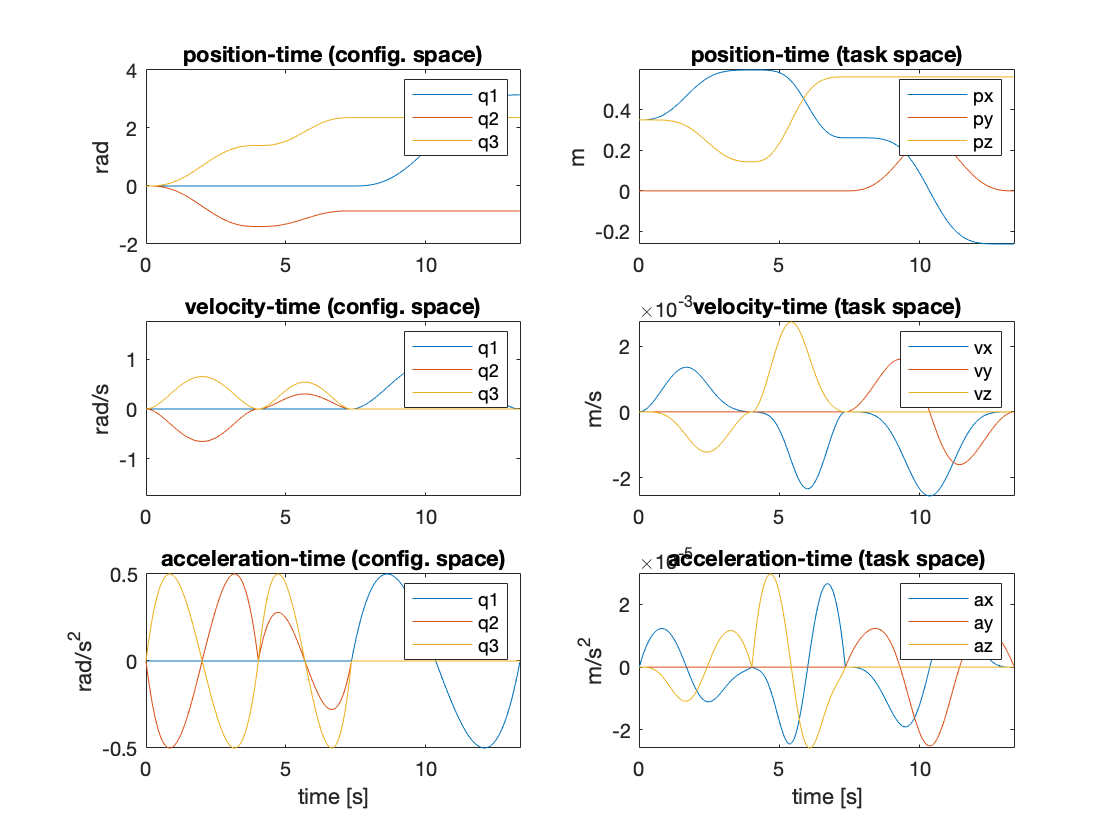

plotTrajectory(t, p1,v1,a1, p2,v2,a2, T, v_max,a_max)

[alert_singularity, idx, border,J_v] = checkSingularity(p1, t)

alert_singularity = 0

idx =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


border = 13.3600

J_v =     0.0000    0.4621    0.2992
   -0.2621    0.0000    0.0000
         0    0.2121    0.0226


alert_singularity

alert_singularity = 0